**Last modified:**

21/05/2024 Jakob Kresse

# Single Particle Tracking

## Aim

This is a live script for SPT analysis using Stephan Blocks and Jakob Kresses Matlab scripts. 

The Documentation is based on a version written by Nadia Peerboom in June 2017 and revised by Dario Conca, Stephan Block and Jakob Kresse afterwards.

All main scripts are contained in the main folder "Template". This folder also contains: 

- The folder “raw”, which collects the raw data of the microscopic images (*e.g.*, the *.nd2 files).

- The folder “incoming”, in which all the movie files (in .tif format) have to be placed before analysis.

- The folder “processed” folder in which all files from the analysis will be placed automatically

- The folder "src" where the sourcecode used can be found

## Materials

- Fiji/ImageJ

- MatLab

## Protocol

The basic tracking procedure is based on 3 different phases A, B and C and can be run interactively from this live script. It is necessary to run phase A first, but phase B and C can be run in arbitrary order or even simultaneously in two MATLAB instances (This only makes sense if your Computer has at least twice as many cores as movies that you are analysing in a batch since each step already runs on multiple threads).

The functions, which are relevant for the corresponding analysis phases, contain the relevant letter in their naming. Depending on the type of tracking analysis (e.g., analysis of equilibrium binding measurements, flow-based measurement etc.), additional analysis phases might be added.

For the standard user this live script is everything thats necessary but if one wants to incorporate this procedure into their own workflow it might be useful to have different main scripts `THINK ON THIS`.

## I. Phase A: Particle Tracking

### Defining the path

Select the path to the movies you want to analyze in the User Interface. This interface displays only directories, so don't be concerned if you don't see any files. This will create the subdirectories described earlier. If the directories already exist be sure to navigate to the directory one above incoming,etc. not inside them. If you do not explicitly define the path this way the** path of the live script will be used as default.**

 
fullScriptPath = matlab.desktop.editor.getActiveFilename;
[scriptDir, ~, ~] = fileparts(fullScriptPath);
% Change directory to the live script's directory
cd(scriptDir);

selected_path = uigetdir;
% Define the names of the subdirectories
subdirs = {'incoming', 'raw', 'processed', 'src'};

% Loop through the subdirectories and create them if they don't exist
for i = 1:length(subdirs)
    subdirPath = fullfile(selected_path, subdirs{i});
    if ~exist(subdirPath, 'dir')
        mkdir(subdirPath);
        disp(['Created directory: ', subdirPath]);
    else
        disp(['Directory already exists: ', subdirPath]);
    end
end

Directory already exists: C:\Users\kr3ss\Desktop\_raw\incoming
Directory already exists: C:\Users\kr3ss\Desktop\_raw\raw
Directory already exists: C:\Users\kr3ss\Desktop\_raw\processed
Directory already exists: C:\Users\kr3ss\Desktop\_raw\src


% Copy .tif files and delete original after confirming copy
tif_dir = dir(fullfile(selected_path, '*.tif'));
for i = 1:length(tif_dir)
    base_str = tif_dir(i).name;
    src_file = fullfile(selected_path, base_str);
    dest_file = fullfile(selected_path, 'incoming', base_str);
    
    try
        copyfile(src_file, dest_file);
        if exist(dest_file, 'file') == 2
            delete(src_file);
        else
            error('File copy failed: %s', base_str);
        end
    catch ME
        fprintf('Error occurred: %s. File was not deleted: %s\n', ME.message, base_str);
    end
end

% Copy .tiff files and delete original after confirming copy
tiff_dir = dir(fullfile(selected_path, '*.tiff'));
for i = 1:length(tiff_dir)
    base_str = tiff_dir(i).name;
    src_file = fullfile(selected_path, base_str);
    dest_file = fullfile(selected_path, 'incoming', base_str);
    
    try
        copyfile(src_file, dest_file);
        if exist(dest_file, 'file') == 2
            delete(src_file);
        else
            error('File copy failed: %s', base_str);
        end
    catch ME
        fprintf('Error occurred: %s. File was not deleted: %s\n', ME.message, base_str);
    end
end

% Copy .nd2 files to 'raw' and delete original after confirming copy
nd2_dir = dir(fullfile(selected_path, '*.nd2'));
for i = 1:length(nd2_dir)
    base_str = nd2_dir(i).name;
    src_file = fullfile(selected_path, base_str);
    dest_file = fullfile(selected_path, 'raw', base_str);
    
    try
        copyfile(src_file, dest_file);
        if exist(dest_file, 'file') == 2
            delete(src_file);
        else
            error('File copy failed: %s', base_str);
        end
    catch ME
        fprintf('Error occurred: %s. File was not deleted: %s\n', ME.message, base_str);
    end
end

% Copy .m files from scriptDir/src to selected_path/src for reproducibility
% Get the directory listing and filter out '.' and '..'
src_dir_listing = dir(fullfile(selected_path, 'src'));
src_dir_listing = src_dir_listing(~ismember({src_dir_listing.name}, {'.', '..'}));

if isempty(src_dir_listing)
    src_dir = dir(fullfile(scriptDir, 'src', '*.m'));
    for i = 1:length(src_dir)
        base_str = src_dir(i).name;
        src_file = fullfile(scriptDir, 'src', base_str);
        dest_file = fullfile(selected_path, 'src', base_str);
        
        try
            copyfile(src_file, dest_file);
            if exist(dest_file, 'file') ~= 2
                error('File copy failed: %s', base_str);
            end
        catch ME
            fprintf('Error occurred: %s. File was not copied: %s\n', ME.message, base_str);
        end
    end
else
    disp("Version of source code at the selected directory will be used for reproducibility. Delete selected_path/src if you wish to use another version.");
end

Version of source code at the selected directory will be used for reproducibility. Delete selected_path/src if you wish to use another version.



clear full_path;
clear fullScriptPath;
clear nd2_dir;
clear src_dir;
clear src_dir_listing;
clear src_file;
clear subdirPath;
clear subdirs;
clear scriptDir;
clear tif_dir;
clear tiff_dir;
clear i;


Number of frames: 100


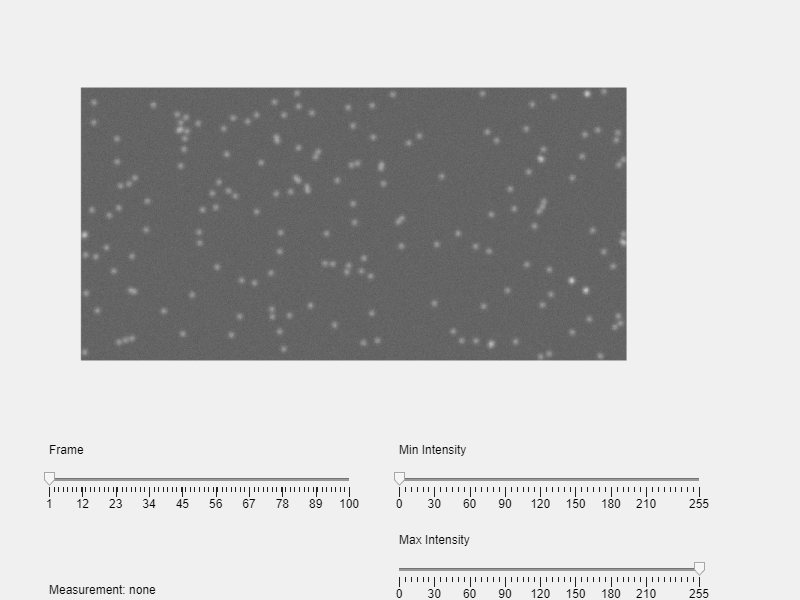

function [selected_path,path_processed,path_incoming]= SetPath()
    %brief: Sadly Matlab is unable to set the path automatically, when
    %changing the directory. This is a workaround to set the path, whenever
    %executing a new code section.
    if evalin('base', 'exist(''selected_path'', ''var'')')
        % Get the full path of the active live script

        selected_path = evalin('base', 'selected_path');
        fullScriptPath = matlab.desktop.editor.getActiveFilename;
        [scriptDir, ~, ~] = fileparts(fullScriptPath);
        % Change directory to the live script's directory
        cd(scriptDir);
        
        %path to files
        path_incoming = fullfile(selected_path, 'incoming/');
        %path to the analysis result
        path_processed = fullfile(selected_path, 'processed/');
    else
        disp('No path was selected explicitly, using the path of this script as default. Click "Set Path" to change this.')
        fullScriptPath = matlab.desktop.editor.getActiveFilename;
        [scriptDir, ~, ~] = fileparts(fullScriptPath);
        % Change directory to the live script's directory
        cd(scriptDir);
        selected_path = scriptDir;
        %path to files
        path_incoming = fullfile(selected_path, 'incoming/');
        %path to the analysis result
        path_processed = fullfile(selected_path, 'processed/');
    end


### Running in parallel

Check this box if you want to run the analysis protocol in parallel on your computers multiple cores. This is recommended if you have multiple movies and work alone on a workstation and can potentially decrease the execution time up to five times. Disable if you share the PC since this can lead to trouble for the other users.

    run_in_parallel = true;
    assignin('base', 'run_in_parallel', run_in_parallel);
    addpath(fullfile(selected_path, 'src'));
    addpath(path_incoming);
    addpath(path_processed);
    clear fullScriptPath;
    clear scriptDir;
end

### I.1 Select a threshold

 Drag the Min and Max cursor all the way to the left. You should now see a white image. Now you increase the Min cursor to increase the threshold. Choosing the right threshold value is a tradeoff between minimizing the noise level, while including as many particles as possible (even the dim ones). The best conditions therefore are very bright particles on a black background. It is ok to leave a little bit of background noise, if this allows you to include most of the particles. 

[~,~,path_incoming]=SetPath();
fluo_cutoff = 130;
 
[~,path_processed,path_incoming]=SetPath();
load_parameters(path_processed);
show_raw_ui(path_incoming, base_str_array(1));

### I.2 Chose a “del” parameter 

The standard procedure to detect the particles uses a local maximum approach (done by “exec_A_detect_local_max_v2.m”), in which the script screens the image (for each frame) using a window (of set size). For each position of the window, the script will search for a local intensity maximum. The pixel position corresponding to this maximum becomes the position of the detected particle. Note that there is no requirement of minimal size (in px) in order for a spot to be considered a particle. The “del” parameter determines the size of this 2D window (having (2*del+1) x (2*del+1) entries) and is typically around 3 or 4 (depending on the particle size and effective pixel size of the camera). The del parameter has been constructed to roughly correspond to the particle size (in pixels) in the image. It therefore depends on the size of the particles and should not be smaller than particle as this will lead to one particle being counted several times. The proper value can be determined by estimating radii (in units of pixel) of several particles. 

Just click two times in the image to make a measurement, which will be displayed in units of pixels in the bottom left corner.

del = 3;

dt is the time interval between images in units of seconds, pix_size is the relative size of a pixel in pixels, dist_cutoff has to the with the linking step and should be kept at this value for now.

dt=1; %Time interval in seconds 

Using the defined dist_cutoff. (parameter_table has no dist_cutoff yet).


pix_size=1; %Pixel size  
dir_cont = dir(strcat(path_incoming,'*.tif'));
num_movies = length(dir_cont);
fluo_cutoff_array = fluo_cutoff*ones(1,num_movies);
del_array = del*ones(1,num_movies);
dt_array = dt*ones(1,num_movies);
pix_size_array = pix_size*ones(1,num_movies);
xstart_array = ones(1,num_movies);
ystart_array = ones(1,num_movies);
xend_array= ones(1,num_movies);
yend_array= ones(1,num_movies);
base_str_array = string({dir_cont.name});
for i= 1:num_movies
    base_str=base_str_array(i);
    img_meta=imfinfo(strcat(path_incoming,base_str));
    xdim=img_meta(1).Width;
    ydim=img_meta(1).Height;
    xend_array(i) = xdim;
    yend_array(i) = ydim;
end
%dist_cutoff_array=30000*ones(1,num_movies); is this necessary?
clear base_str;
clear i;
clear del;
clear dt;
clear fluo_cutoff;
clear img_meta;
clear pix_size;
clear xdim;
clear ydim;
 

If you want to analyze just a crop of the images in each movie you can set xstart, xend, ystart, yend by chosing different parameters for different movies. The default is analyzing the complete movie.

### I.3 Chose different parameters for different movies (optional)

If this script was run before the parameters are safed to a parameter_table.csv and can be loaded for reproducing the analysis.

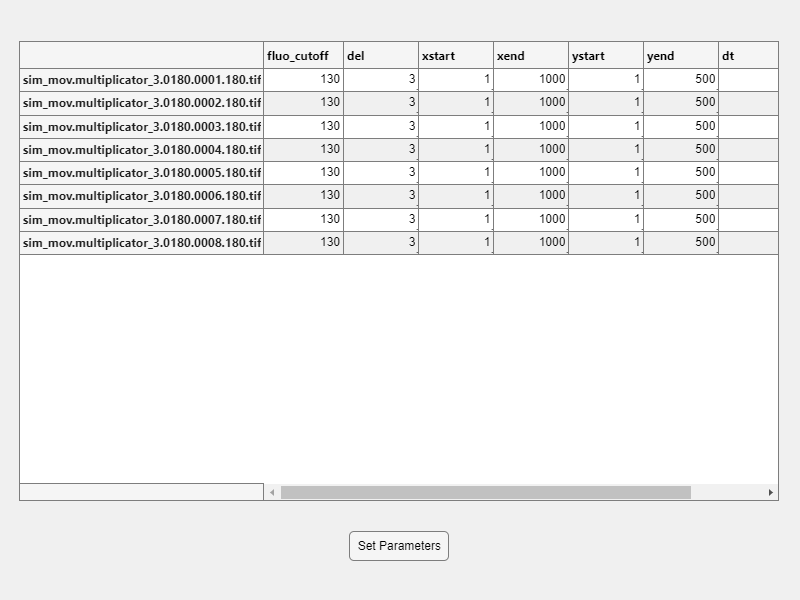

 
[~,path_processed,~]=SetPath();

load_parameters(path_processed);

Sometimes, it happens that not all movies can be analyzed using the same parameters. In this case change the corresponding parameters by pressing the **"Change Parameters"** button, editing the parameters in the respective rows and pressing **"Set Parameters"**.

 
[~,~,path_incoming]=SetPath();
dir_cont = dir(strcat(path_incoming,'*.tif'));
base_str_array = string({dir_cont.name});
% Create a uifigure
fig = uifigure('Name', 'Movie Parameters Input', 'Position', [100, 100, 800, 600]);

% Define the parameter names
param_names = {'fluo_cutoff', 'del', 'xstart', 'xend', 'ystart', 'yend', 'dt', 'pix_size'};
num_params = length(param_names);

% Initialize the data with default values
data = cell(num_movies, num_params);

data_table = 8×9 table
                     base_str                      fluo_cutoff    del    xstart    xend    ystart    yend    dt    pix_size
    ___________________________________________    ___________    ___    ______    ____    ______    ____    __    ________

    "sim_mov.multiplicator_3.0180.0001.180.tif"        130         3       1       1000      1       500     1        1    
    "sim_mov.multiplicator_3.0180.0002.180.tif"        130         3       1       1000      1       500     1        1    
    "sim_mov.multiplicator_3.0180.0003.180.tif"        130         3       1       1000      1       500     1        1    
    "sim_mov.multiplicator_3.0180.0004.180.tif"   

for i = 1:num_movies
    data{i, 1} = fluo_cutoff_array(i);
    data{i, 2} = del_array(i);
    data{i, 3} = xstart_array(i);
    data{i, 4} = xend_array(i);
    data{i, 5} = ystart_array(i);
    data{i, 6} = yend_array(i);
    data{i, 7} = dt_array(i);
    data{i, 8} = pix_size_array(i);
end

% Create the uitable
t = uitable(fig, 'Data', data, 'ColumnName', param_names, 'RowName', base_str_array, ...
    'ColumnEditable', true(1, num_params), 'Position', [20 100 760 460]);

% Create a button to save data
btn = uibutton(fig, 'Text', 'Set Parameters', 'Position', [350, 40, 100, 30], ...
    'ButtonPushedFcn', @(btn,event) save_data(t, param_names));
clear data;
clear i;
clear num_movies;
clear num_params;
clear param_names;
clear btn;
clear fig;
clear t;

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
tracking:sim_mov.multiplicator_3.0180.0005.180.tif
tracking:sim_mov.multiplicator_3.0180.0002.180.tif
tracking:sim_mov.multiplicator_3.0180.0008.180.tif
tracking:sim_mov.multiplicator_3.0180.0001.180.tif
tracking:sim_mov.multiplicator_3.0180.0004.180.tif
tracking:sim_mov.multiplicator_3.0180.0006.180.tif
tracking:sim_mov.multiplicator_3.0180.0007.180.tif
tracking:sim_mov.multiplicator_3.0180.0003.180.tif


[~,~,~]=SetPath();
data_table = table(base_str_array', fluo_cutoff_array', del_array', xstart_array', xend_array', ystart_array', yend_array', dt_array', pix_size_array',...
        'VariableNames', {'base_str', 'fluo_cutoff', 'del', 'xstart', 'xend', 'ystart', 'yend', 'dt', 'pix_size'});
data_table
clear data_table;

### I.4 Particle detection step

The particles will be detected in all movies by calling the “exec_A_detect_local_max_v2.m” script. When the detection is done, a matrix called “xy_schw” will appear in your workspace. This matrix now contains following information for each detected particle: 

**Col#** **1**: Particle ID 

**Col#** **2**: Frame number 

**Col#** **3**: x position 

**Col#** **4**: y position 

**Col#** **5**: Intensity value of the local maximum (= particle’s peak intensity)

**Col#** **6**: Track ID (only assigned for particles of 1st frame for now) 

The remaining columns will be filled out at later stages of the analysis. For each included movie, a separate xy_schw matrix will be generated and stored in the “processed” folder using the file naming $Name_of_movie.tracks_raw.dat.mat. The parameters used will be saved to a parameter_table.csv in processed and loaded for the following analysis steps. `THINK ABOUT REEXECUTION`

 
[~,path_processed,path_incoming]=SetPath();
dir_cont = dir(strcat(path_incoming,'*.tif'));

data_table = 8×9 table
                     base_str                      fluo_cutoff    del    xstart    xend    ystart    yend    dt    pix_size
    ___________________________________________    ___________    ___    ______    ____    ______    ____    __    ________

    "sim_mov.multiplicator_3.0180.0001.180.tif"        130         3       1       1000      1       500     1        1    
    "sim_mov.multiplicator_3.0180.0002.180.tif"        130         3       1       1000      1       500     1        1    
    "sim_mov.multiplicator_3.0180.0003.180.tif"        130         3       1       1000      1       500     1        1    
    "sim_mov.multiplicator_3.0180.0004.180.tif"   

if ~isempty(dir_cont)
    %loop over movies
    if(run_in_parallel && length(dir_cont) > 1)
        parfor iF=1:length(dir_cont) 
           base_str=dir_cont(iF).name;
           img_meta=imfinfo(strcat(path_incoming,base_str));
           Ndim=length(img_meta);
           xdim=img_meta(1).Width;
           ydim=img_meta(1).Height;
           display(strcat('tracking: ',base_str))
           exec_A_detect_local_max_v2(xstart_array(iF), xend_array(iF), ystart_array(iF), yend_array(iF), ...
                                      fluo_cutoff_array(iF), del_array(iF), ...
                                      base_str, path_incoming, path_processed, ... 
                                      Ndim, xdim, ydim);
           %disp(['Detected ', num2str(size(data, 1)), ' particles in total over all frames.'])
        end
    else

Using the defined dist_cutoff. (parameter_table has no dist_cutoff yet).


Number of frames: 100
Displaying frame: 1


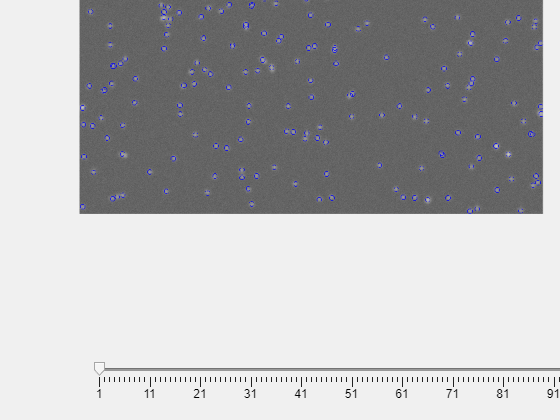

        for iF=1:length(dir_cont) 

           base_str=dir_cont(iF).name;
           img_meta=imfinfo(strcat(path_incoming,base_str));
           Ndim=length(img_meta);
           xdim=img_meta(1).Width;
           ydim=img_meta(1).Height;
           display(strcat('tracking: ',base_str))
           exec_A_detect_local_max_v2(xstart_array(iF), xend_array(iF), ystart_array(iF), yend_array(iF), ...
                                      fluo_cutoff_array(iF), del_array(iF), ...
                                      base_str, path_incoming, path_processed, ... 
                                      Ndim, xdim, ydim);
        end
    end
else
    warning("Incoming seems to be empty.");
end 
data_table = table(base_str_array', fluo_cutoff_array', del_array', xstart_array', xend_array', ystart_array', yend_array', dt_array', pix_size_array',  ...
    'VariableNames', {'base_str', 'fluo_cutoff', 'del', 'xstart', 'xend', 'ystart', 'yend', 'dt', 'pix_size'});

Using the defined dist_cutoff. (parameter_table has no dist_cutoff yet).



%save the parameters used in a readable format
full_path = fullfile(path_processed, 'parameter_table.csv');
% Write the table to a CSV file
writetable(data_table, full_path);
data_table
clear data_table;

    "Linking:sim_mov.multiplicator_3.0180.0006.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0008.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0004.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0003.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0001.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0007.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0002.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0005.180.tif"



#### I.5 Visual Inspection

You can chose to either call the show_detection function on the videos which will create *detection.tif files in path_processed and inspect these with ImageJ, or to call show_detection_ui and inspect the videos in Matlab.

This will both create images where the local max of step A are highlighted in blue.

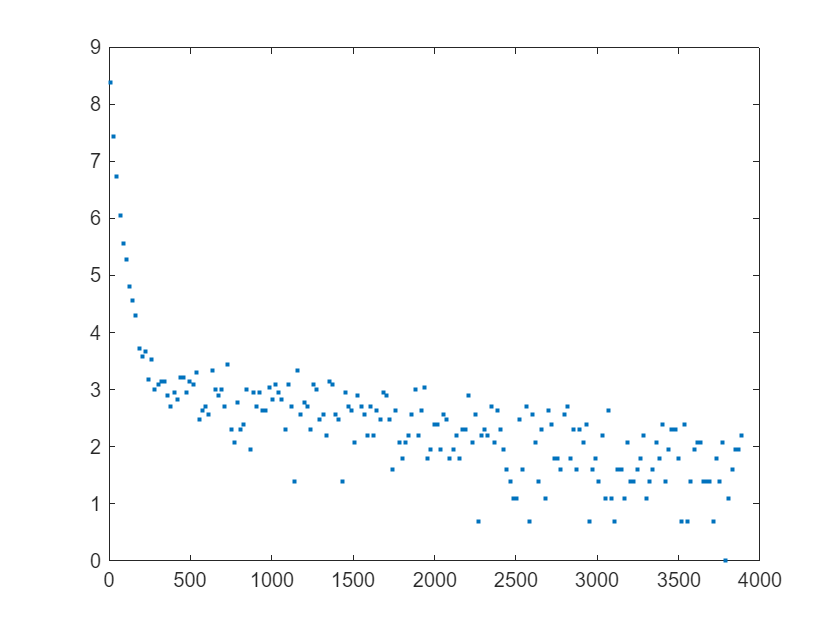

sim_mov.multiplicator_3.0180.0001.180.tif.tracks_v2.30000.dat.mat-64.5556


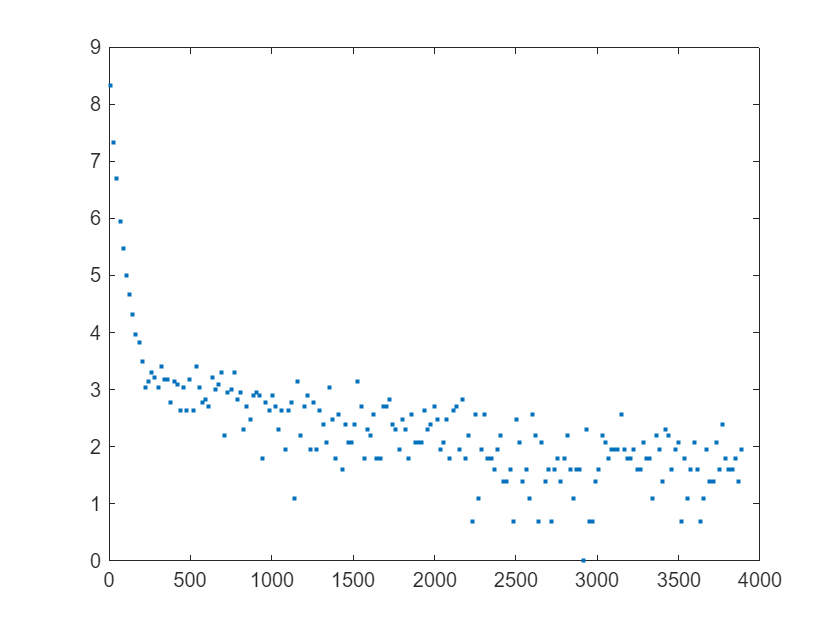

sim_mov.multiplicator_3.0180.0002.180.tif.tracks_v2.30000.dat.mat-63.1536


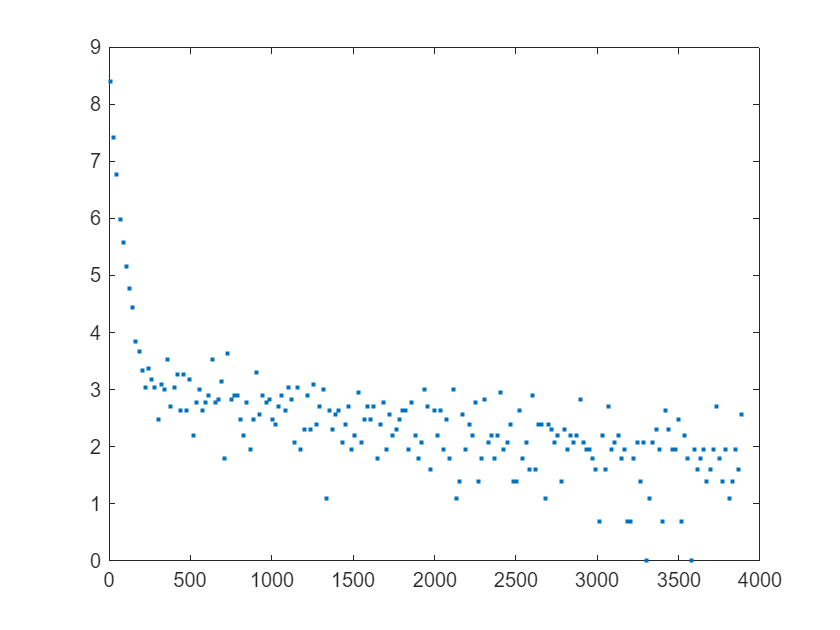

sim_mov.multiplicator_3.0180.0003.180.tif.tracks_v2.30000.dat.mat-64.7992


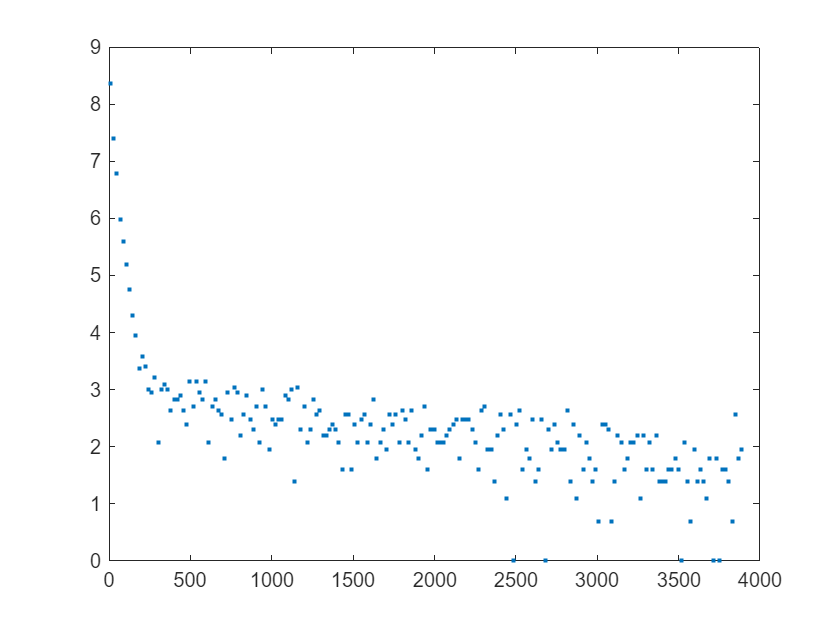

sim_mov.multiplicator_3.0180.0004.180.tif.tracks_v2.30000.dat.mat-64.1603


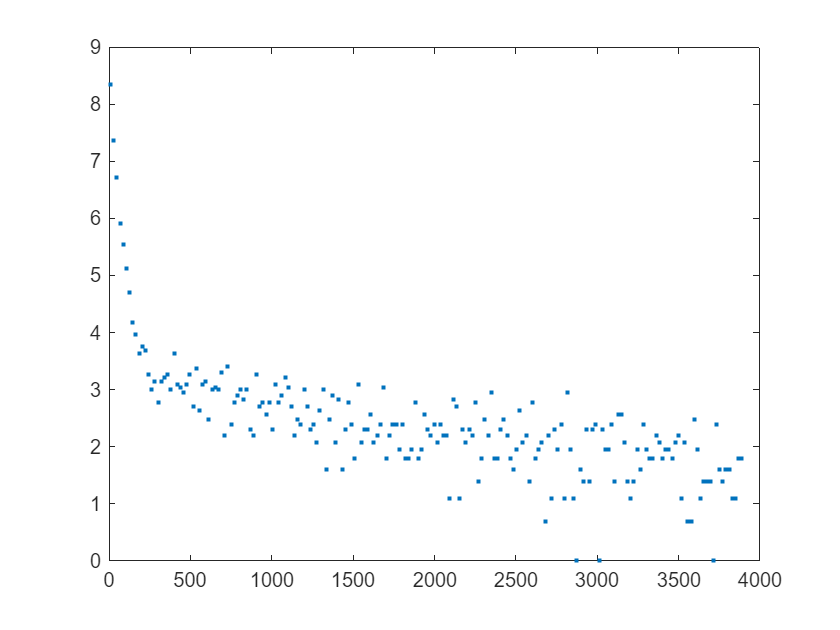

sim_mov.multiplicator_3.0180.0005.180.tif.tracks_v2.30000.dat.mat-62.426


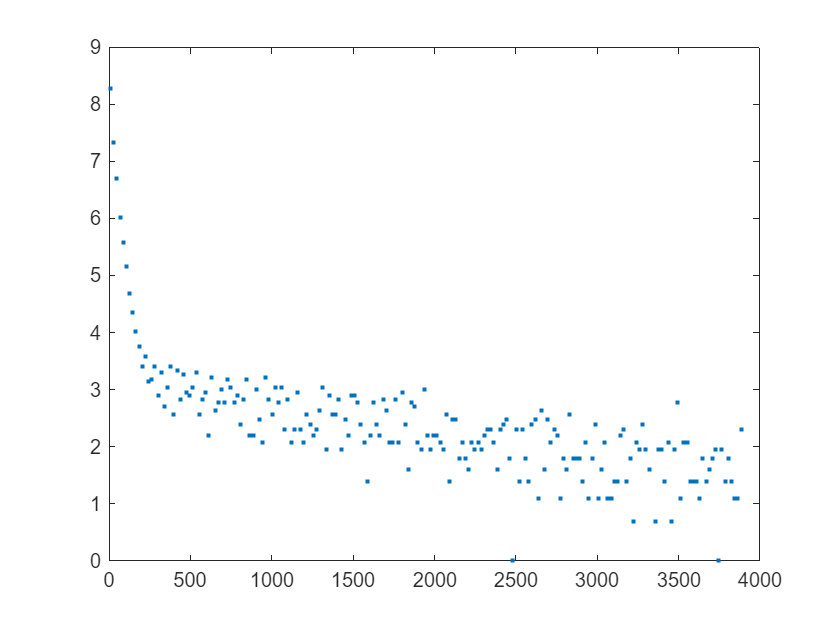

sim_mov.multiplicator_3.0180.0006.180.tif.tracks_v2.30000.dat.mat-63.7341


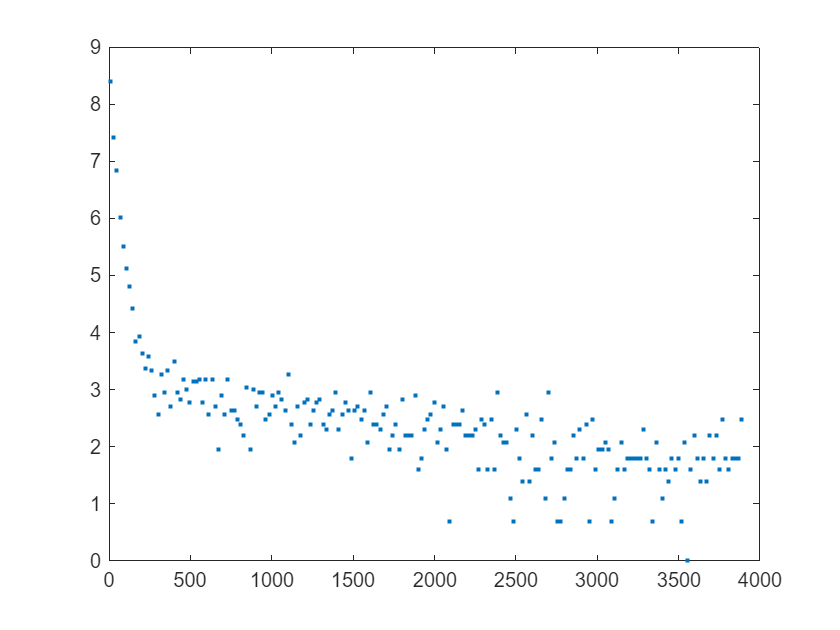

sim_mov.multiplicator_3.0180.0007.180.tif.tracks_v2.30000.dat.mat-69.0683


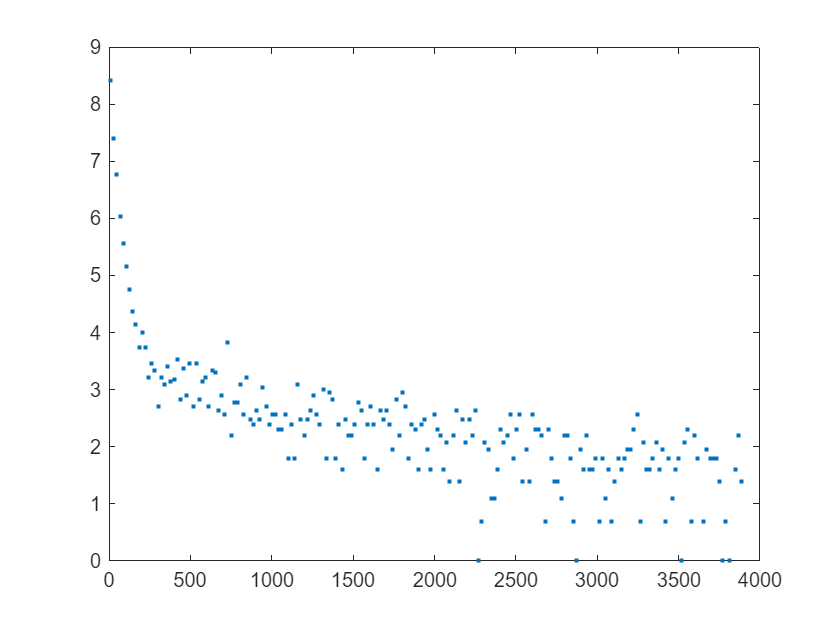

sim_mov.multiplicator_3.0180.0008.180.tif.tracks_v2.30000.dat.mat-68.0545


 
[~,path_processed,path_incoming]=SetPath();
load_parameters(path_processed);


for i =1:length(base_str_array)
    disp(base_str_array(i))
    show_detection(path_processed, path_incoming, base_str_array(i));
end

 
[~,path_processed,path_incoming]=SetPath();
load_parameters(path_processed);

Using the defined dist_cutoff. (parameter_table has no dist_cutoff yet).


show_detection_ui(path_processed, path_incoming, base_str_array(1));

## II. Phase B: Linking of events

In this phase, the detected particles for each frame will be linked to the detected particles of the next frame. The standard procedure to do this is based on a “nearest-neighbor” algorithm (implemented in “exec_B_link_events_NN_v4.m”), implying that each particle will be linked to the closest particle in the next frame. Note that a 2-step-approach is used here: when linking particles from two consecutive frames, the algorithm starts with the pair of closest positions. This pair is then linked and removed from the possibilities for linking. One then continues with the next pair of closest position. Note that with this approach a particle in frame N is not necessarily linked to the closest particle in frame N+1, since that particle could already be linked to another (closer) particle in frame N. For not too large events densities (*i.e.*, for average particles distances being significantly larger than the average distance travelled by the particles between adjacent frames), this procedure works very reliably. For higher densities, algorithms that make a global analysis of all linking steps (such as the so-called Hungarian algorithm) may have superior performance.

The linking will be done in two iterations (described in detail in II.1 and II.2 below): For the first one, a distance cutoff of 30000 (default value in AB_main.m) will be used, which ensures that **all** particles will be linked, for which a “partner” is found in the next frame. This will of course lead to errors, as particles can have vanished (by detachment or bleaching) or appeared (by attachment). Furthermore, errors can occur from situations where trajectories of 2 particles come too close to each other. In the second iteration, the distance cutoff is set to a smaller value that is determined from the linking statistics as described below (refinement of the distance cutoff; see II.2).

Note that, in order to reduce errors due to trajectories that come too close to each other, one should adapt the surface coverage of the particles. As a rule of thumb, the typical distance that a particle moves between 2 consecutive frames should be 10 times smaller than the average distance between two neighboring particles.  

### II.1 Linking with high distance cutoff (first linking iteration) `THINK ABOUT PARAMTER TABLE`

This code section will do the linking (using a distance cutoff of 30000) by calling the “exec_B_link_events_NN_v4.m” function. 

The “xy_schw” matrix has now been updated with new information: 

**Col# 1: **Particle ID

**Col# 2:** Track ID (linked particles of different frames have the same track ID) 

**Col# 3:** Squared displacement (Δx2 + Δy2) between linked particles of 2 consecutive frames (in units of pixel²). 

**Col# 4:** Particle’s peak intensity in the previous frame

**Col# 5**: Logical argument - 1: the track of this particle continues in the next frame; 0: the track of this particle terminates at this frame. 

For each included movie, a separate xy_schw matrix will be generated and stored in the “processed” folder using the file naming $Name_of_movie.tracks_v2.30000.dat.mat. This might take several minutes-hours.

 
[~,path_processed,~]=SetPath();
load_parameters(path_processed);
%loop over movies with their correspinding parameters
if(run_in_parallel && length(dir_cont) > 1)
    parfor iF=1:length(base_str_array)  
       display(strcat('Linking: ',base_str_array(iF)))

Using the defined dist_cutoff. (parameter_table has no dist_cutoff yet).


       exec_B_link_events_LAP_v2(path_processed,base_str_array(iF),30000);
    end 
else
     for iF=1:length(base_str_array)  
       display(strcat('Linking: ',base_str_array(iF)))
       exec_B_link_events_LAP_v2(path_processed,base_str_array(iF),30000);
     end 
end

### II.2 Linking with refined distance cutoff (second linking iteration) 	

In this step, the distance cutoff value is refined. Press "**Show distance cutoff"**. It will generate a histogram of the squared displacements stored in column 7 (right, y-axis is the ln of the frequency). You can “zoom in” or out by changing the parameter max_dist_cutoff, which determines the largest displacement shown in the histogram. 

max_dist_cutoff =  3900;
[~,path_processed,~]=SetPath();
B_show_distance_cutoff(path_processed, max_dist_cutoff)

For perfect random walkers, the squared displacements would follow an exponential decay, which follows a straight line in this semi-logarithmic plot (the slope of which is inversely proportional to the average diffusion coefficient). Errors done in the linking process will generate squared displacements that deviate from this ideal distribution, typically generating a noise floor. A typical histogram is therefore given by a straight line superimposed on a noise floor as shown in the figure. The noise floor dominates the histogram for relatively large values of the squared displacements. As this region of the histogram mainly corresponds to linking errors, it does not make sense to allow these linking steps to be done. This can be achieved by choosing a distance cutoff value, which equals the squared displacement value at the intersection between linear decay and noise flow (around 1000 in the example above). If the noise level is low, one can consider high cutoff values, as the total number of false events will be very low. 				

Note that one can calculate a theoretical cutoff value by calculating the mean- squared-displacement of the particle (typical squared distance that a particle moves between 2 consecutive frames). Since the squared displacement follows an exponential decay, choosing a distance cutoff of 3 times this value will include 99% of the correct events. However, this picture does not include the impact of noise, which is present in all tracking experiments, and hence, the selection of the cutoff should be based on the above displayed plot. 				

Pressing the Button **“Show distance cutoff”** will display this histogram for each included movie. Often, the crossover from decay to noise floor takes place at similar squared displacement values. If the distance cutoff values differ significantly across the movies, it is necessary to enter the correct value by pressing **"Change Distance Cutoff"**.  After this step, all movies should have a distance cutoff value being significantly smaller than 30,000. If this step was executed before the dist_cutoff can be loaded from the parameter_table.

If you chose to stop the analysis procedure for a movie at this point you can set the "run" parameter to 0 and the linking will not be executed for this movie.

[~,path_processed,~]=SetPath();
load_parameters(path_processed);
 
dist_cutoff = 400;
dist_cutoff_array = dist_cutoff * ones(1,length(base_str_array));
run_linking_array = ones(1,length(base_str_array));

 
[~,path_processed,~]=SetPath();
load_parameters(path_processed);
run_linking_array = ones(1,length(base_str_array));

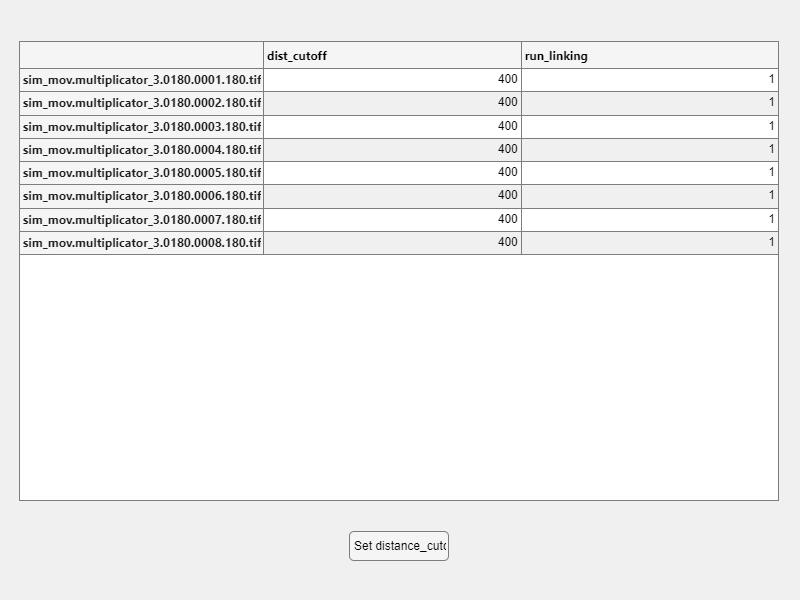

 
% Create a uifigure
fig = uifigure('Name', 'Movie Parameters Input', 'Position', [100, 100, 800, 600]);


% Define the parameter names
param_names = {'dist_cutoff', 'run_linking'};
num_params = length(param_names);
num_movies = length(base_str_array);
% Initialize the data with default values
data = cell(num_movies, num_params);
for i = 1:num_movies
    data{i,1} = dist_cutoff_array(i);
    data{i,2} = 1;
end

data_table = 8×11 table
                     base_str                      fluo_cutoff    del    xstart    xend    ystart    yend    dt    pix_size    dist_cutoff    run_linking
    ___________________________________________    ___________    ___    ______    ____    ______    ____    __    ________    ___________    ___________

    "sim_mov.multiplicator_3.0180.0001.180.tif"        130         3       1       1000      1       500     1        1            400             1     
    "sim_mov.multiplicator_3.0180.0002.180.tif"        130         3       1       1000      1       500     1        1            400     


% Create the uitable
t = uitable(fig, 'Data', data, 'ColumnName', param_names, 'RowName',base_str_array, ...
    'ColumnEditable', true(1, num_params), 'Position', [20 100 760 460]);

% Create a button to save data
btn = uibutton(fig, 'Text', 'Set distance_cutoff', 'Position', [350, 40, 100, 30], ...
    'ButtonPushedFcn', @(btn,event) save_dist_cutoff(t, param_names));
clear btn;
clear data;
clear fig;
clear i;
clear t;

    "Linking:sim_mov.multiplicator_3.0180.0006.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0008.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0004.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0003.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0001.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0007.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0002.180.tif"

    "Linking:sim_mov.multiplicator_3.0180.0005.180.tif"



[~,~,~]=SetPath();
    data_table = table(base_str_array', fluo_cutoff_array', del_array', xstart_array', xend_array', ystart_array', yend_array', dt_array', pix_size_array',dist_cutoff_array',run_linking_array',...
    'VariableNames', {'base_str', 'fluo_cutoff', 'del', 'xstart', 'xend', 'ystart', 'yend', 'dt', 'pix_size','dist_cutoff','run_linking'});
data_table

**Run the linking step** again to repeat the linking step (now with refined distance cutoff values). For each included movie, a separate xy_schw matrix will be generated and stored in the “processed” folder using the file naming $Name_of_movie.tracks_v2.xxx.dat.mat (with xxx denoting the distance cutoff value chosen for the corresponding movie). In this way, it is possible to test the impact of different distance cutoff values on the linking result (see next section). 

 
[~,path_processed,path_incoming]=SetPath();
dir_cont = dir(strcat(path_incoming,'*.tif'));
if(run_in_parallel && length(base_str_array) > 1)
    parfor iF=1:length(base_str_array) 
        base_str=base_str_array(iF); 

data_table = 8×10 table
                     base_str                      fluo_cutoff    del    xstart    xend    ystart    yend    dt    pix_size    dist_cutoff
    ___________________________________________    ___________    ___    ______    ____    ______    ____    __    ________    ___________

    "sim_mov.multiplicator_3.0180.0001.180.tif"        130         3       1       1000      1       500     1        1            400    
    "sim_mov.multiplicator_3.0180.0002.180.tif"        130         3       1       1000      1       500     1        1            400    
    "sim_mov.multiplicator_3.0180.0003.180.tif"        130         3       1   

        if run_linking_array(iF)
           display(strcat('Linking: ',base_str))
           exec_B_link_events_LAP_v2(path_processed,base_str_array(iF),dist_cutoff_array(iF));
        else
           display(strcat('Skipped: ',base_str));
        end
    end 	
else
    for iF=1:length(base_str_array) 
        base_str=base_str_array(iF); 
        if run_linking_array(iF)
           display(strcat('Linking: ',base_str))
           exec_B_link_events_LAP_v2(path_processed,base_str_array(iF),dist_cutoff_array(iF));
        else
           display(strcat('Skipped: ',base_str));
        end
    end 	
end
data_table = table(base_str_array', fluo_cutoff_array', del_array', xstart_array', xend_array', ystart_array', ...
    yend_array', dt_array', pix_size_array', dist_cutoff_array', ...
    'VariableNames', {'base_str', 'fluo_cutoff', 'del', 'xstart', 'xend', 'ystart', 'yend', 'dt', 'pix_size','dist_cutoff'});

%save the parameters used in a readable format
full_path = fullfile(path_processed, 'parameter_table.csv');
% Write the table to a CSV file
writetable(data_table, full_path);

data_table

### II.3 Visual inspection 

To verify the chosen cutoff value, you can press **"Show Tracks". **For each trajectory, this function creates a .tif movie file, which shows on the left side the area from the raw movie, in which the particle moves, and the detected particle position as a bright dot on the right side (projected on a black area). If possible, up to five frames before/after the corresponding track starts/ends are included, which allows to identify, why the trajectory terminated (as the raw movie ended, as its peak intensity fell below the intensity threshold, as the trajectory crossed another trajectory, etc.) or if the particle is already present before the trajectory started (*e.g.*, for particles with peak intensities close to the intensity threshold or when using a too small value of the distance cutoff). 

Too large values of the distance cutoff will generate tracks, which hop between different particles. Too small values of the distance cutoff will cause the trajectories to split in multiple trajectories, which can be identified as the movies will cover not only the duration of the track but also additional 5 frames before and after the track started/ended. If too many of such events are observed (> 10% of tracks), a lower/higher distance cutoff value should be considered.

This evaluation of the linking quality is tedious but important, as most of the above-mentioned linking errors cannot be resolved by simply generating an overview plot of all tracks (done using the function B_show_A_tracks_v2.m). This step should always be done when tracking a new system. If the system has been investigated several times (providing reference values for the intensity and distance cutoff), this step may be skipped.	`ORIGINALVERSION ABWARTEN`

### *III. Phase C: Sub-pixel detection* 

The final step of the basic analysis is the refinement of the particle positions using a sub-pixel detection procedure, which typically improves the localization accuracy significantly. The particle position will now be determined by fitting a point-spread function through the object.  

*Hint*: Note that this is the most computing expensive part and might take several hours.

Press "**Subpixel Detection**". The data of this analysis is stored after each 10000 events. If, for some reason, the analysis breaks down, it will pick up from the last saved file.

The “xy_schw” matrix has now been updated with new information: 

**Col# 1: **Particle ID

**Col# 2**: new (sub-pix) x position 

**Col# 3**: new (sub-pix) y position 

**Col# 4**: peak intensity of the particle (corrected by the background intensity)

**Col# 5**: radius of the point spread function (in pixel)

For each included movie, a separate xy_schw matrix will be generated and stored in the “processed” folder using the file naming $Name_of_movie.tracks_v2_sub.dat.mat.

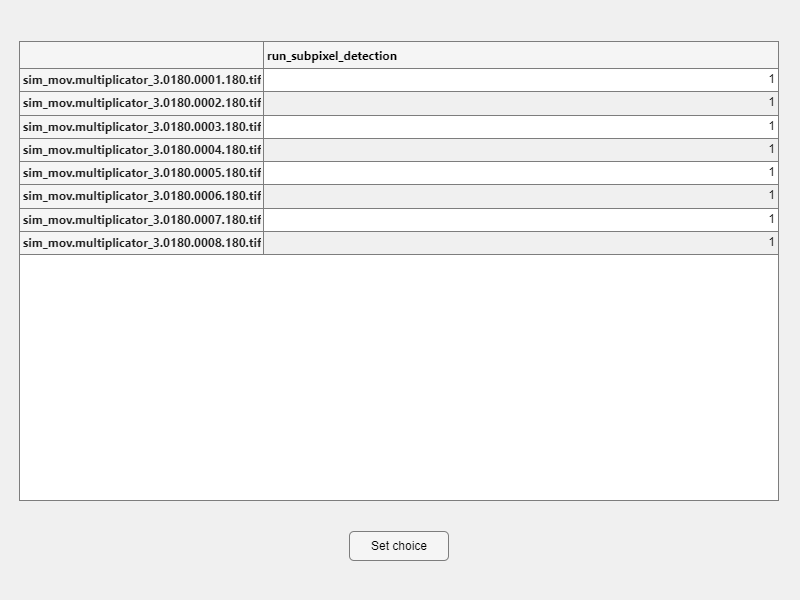

 
[~,path_processed,path_incoming]=SetPath();
dir_cont = dir(strcat(path_incoming,'*.tif'));

load_parameters(path_processed);
% Create a uifigure
fig = uifigure('Name', 'Movie Parameters Input', 'Position', [100, 100, 800, 600]);

% Define the parameter names
param_names = {'run_subpixel_detection'};
num_params = length(param_names);
num_movies = length(dir_cont);
% Initialize the data with default values
data = cell(num_movies, num_params);

for i = 1:num_movies
    data{i,1} = 1;
end

% Create the uitable
t = uitable(fig, 'Data', data, 'ColumnName', param_names, 'RowName',base_str_array, ...
    'ColumnEditable', true(1, num_params), 'Position', [20 100 760 460]);

% Create a button to save data
btn = uibutton(fig, 'Text', 'Set choice', 'Position', [350, 40, 100, 30], ...
    'ButtonPushedFcn', @(btn,event) save_run_array(t, param_names)); 

function save_run_array(table_handle, param_names)
    data = table_handle.Data;
    run_array = cell2mat(data(:, strcmp(param_names, 'run_subpixel_detection')))';

    assignin('base','run_subpixel_array',run_array);
    disp('Data saved to workspace as arrays');
end
clear btn;
clear data;
clear fig;
clear i;
clear num_movies;
clear num_params;
clear param_names;
clear t;

    "Detecting:sim_mov.multiplicator_3.0180.0006.180.tif"

    "Detecting:sim_mov.multiplicator_3.0180.0008.180.tif"

    "Detecting:sim_mov.multiplicator_3.0180.0004.180.tif"

    "Detecting:sim_mov.multiplicator_3.0180.0003.180.tif"

    "Detecting:sim_mov.multiplicator_3.0180.0001.180.tif"

    "Detecting:sim_mov.multiplicator_3.0180.0007.180.tif"

    "Detecting:sim_mov.multiplicator_3.0180.0002.180.tif"

    "Detecting:sim_mov.multiplicator_3.0180.0005.180.tif"

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1777.968784 

psf_size=7.872 pixels
subpix detected:1, x0=172.6252, x0_raw=174, y0=5.8265, y0_raw=6
psf_size=7.8892 pixels
subpix detected:1, x0=643.3173, x0_raw=644, y0=6.1077, y0_raw=6
 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1367.064703 

psf_size=7.8422 pixels
subpix detected:1, x0=

[~,path_processed,path_incoming]=SetPath();
load_parameters(path_processed);
if(~exist('run_subpixel_array', 'var'))
    run_subpixel_array = ones(1,length(base_str_array));%run for all movies as default
end

data_table = 8×11 table
                     base_str                      fluo_cutoff    del    xstart    xend    ystart    yend    dt    pix_size    dist_cutoff    run_subpixel
    ___________________________________________    ___________    ___    ______    ____    ______    ____    __    ________    ___________    ____________

    "sim_mov.multiplicator_3.0180.0001.180.tif"        130         3       1       1000      1       500     1        1            400             1      
    "sim_mov.multiplicator_3.0180.0002.180.tif"        130         3       1       1000      1       500     1        1            400  

Number of frames: 100
Displaying frame: 1


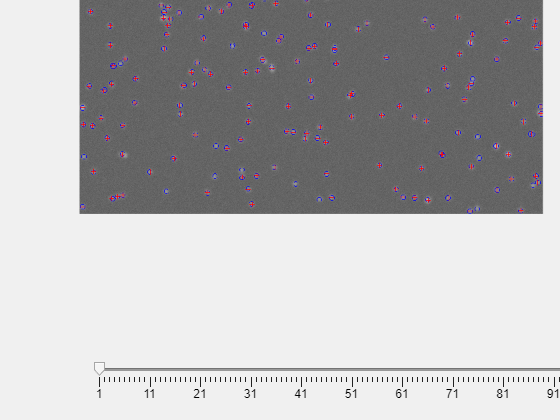

if(run_in_parallel && length(dir_cont) > 1)
    parfor iF=1:length(base_str_array) 
          base_str=base_str_array(iF);
          if(run_subpixel_array(iF))
              img_meta=imfinfo(strcat(path_incoming,base_str));
              Ndim=length(img_meta);
              xdim=img_meta(1).Width;
              ydim=img_meta(1).Height;
              display(strcat('Detecting: ',base_str))
                exec_C_subpix_det_Gauss_v2(xstart_array(iF), xend_array(iF), ystart_array(iF), yend_array(iF), ...
                                       del_array(iF), base_str, path_incoming, path_processed, xdim, ydim);
          else
              display(strcat('Skipped: ',base_str))
          end
    end
else
    for iF=1:length(base_str_array) 

          base_str=base_str_array(iF);
          if(run_subpixel_array(iF))
              img_meta=imfinfo(strcat(path_incoming,base_str));
              Ndim=length(img_meta);
              xdim=img_meta(1).Width;
              ydim=img_meta(1).Height;
              display(strcat('Detecting: ',base_str))
                exec_C_subpix_det_Gauss_v2(xstart_array(iF), xend_array(iF), ystart_array(iF), yend_array(iF), ...
                                       del_array(iF), base_str, path_incoming, path_processed, xdim, ydim);
          else
              display(strcat('Skipped: ',base_str))
          end
    end
end
data_table = table(base_str_array', fluo_cutoff_array', del_array', xstart_array', xend_array', ystart_array', ...
    yend_array', dt_array', pix_size_array', dist_cutoff_array',run_subpixel_array', ...
    'VariableNames', {'base_str', 'fluo_cutoff', 'del', 'xstart', 'xend', 'ystart', 'yend', 'dt', 'pix_size','dist_cutoff','run_subpixel'});

data_table

#### III.2 Visual Inspection

You can chose to either call the show_detection function on the videos which will create *detection.tif files in path_processed and inspect these with ImageJ, or to call show_detection_ui and inspect the videos in Matlab.

This will both create images where the local max of step A are highlighted in blue and the subpixel detection maxima are highlighted in red. 

 
[~,path_processed,path_incoming]=SetPath();
load_parameters(path_processed);

for i =1:length(base_str_array)
    disp(base_str_array(i))
    show_detection(path_processed, path_incoming, base_str_array(i));
end

 
[~,path_processed,path_incoming]=SetPath();
load_parameters(path_processed);
show_detection_ui(path_processed, path_incoming, base_str_array(1));

### *Phase D: Extra Analyses *

#### 1.    Create main scripts

 For the following analysis steps this tool can be used to create scripts with the procedures which can then be run (1.1) . Alternatively one can run these scripts from within this live script (1.2).

#### 1. 1.  Create scripts

 
[selected_path,path_processed,path_incoming]=SetPath();
extra_analysis = dir(fullfile(selected_path,'/src/','exec_D_*'));
extra_analysis_string = string({extra_analysis.name});
for i = 1:length(extra_analysis_string)
    [~, file_names_without_extension(i), ~] = fileparts(extra_analysis_string(i));
end

 
[~,path_processed,path_incoming]=SetPath();
load_parameters(path_processed);
exec = file_names_without_extension(5);
fidA=fopen(strcat(selected_path,'/AD_main.m'),'w');
for iF = 1:length(base_str_array)
   base_str=base_str_array(iF);
   img_meta=imfinfo(strcat(path_incoming,base_str));
   Ndim=length(img_meta);
   xdim=img_meta(1).Width;
   ydim=img_meta(1).Height;
   fluo_cutoff = fluo_cutoff_array(iF);
   del = del_array(iF);  
   xstart = xstart_array(iF);
   xend = xend_array(iF);
   ystart = ystart_array(iF);
   yend = yend_array(iF);
   dt = dt_array(iF);
   pix_size = pix_size_array(iF); 
   dist_cutoff = dist_cutoff_array(iF);
    fprintf(fidA, '%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%\n');
    fprintf(fidA, 'clear;\n');
    fprintf(fidA, '\n');
    fprintf(fidA, 'addpath(fullfile(pwd, ''src''));\n');
    
    fprintf(fidA, strcat('path_incoming=''./incoming/ '';\n'));
    fprintf(fidA, strcat('path_processed=''./processed/'';\n'));
    fprintf(fidA, strcat('base_str=''', base_str, ''';\n'));
    fprintf(fidA, strcat('Ndim=', num2str(Ndim), ';\n'));
    fprintf(fidA, strcat('xdim=', num2str(xdim), ';\n'));
    fprintf(fidA, strcat('ydim=', num2str(ydim), ';\n'));
    fprintf(fidA, strcat('xstart=', num2str(xstart), ';\n'));
    fprintf(fidA, strcat('xend=', num2str(xend), ';\n'));
    fprintf(fidA, strcat('ystart=', num2str(ystart), ';\n'));
    fprintf(fidA, strcat('yend=', num2str(yend), ';\n'));
    fprintf(fidA, strcat('dt=', num2str(dt), ';\n'));
    fprintf(fidA, strcat('pix_size=', num2str(pix_size), ';\n'));
    fprintf(fidA, strcat('del=', num2str(del), ';\n'));
    fprintf(fidA, strcat('dist_cutoff=', num2str(dist_cutoff), ';\n'));
    fprintf(fidA, strcat('fluo_cutoff=', num2str(fluo_cutoff), ';\n'));
    fprintf(fidA, '\n');
    fprintf(fidA, 'display(strcat(''tracking: '', base_str))\n');
    fprintf(fidA, strcat(exec, ';\n'));
    fprintf(fidA, '%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%\n');
    fprintf(fidA, '\n');
end
fclose(fidA);

#### 1.2. Run extra analysis within livescript

Feel free to copy paste the hidden code to have the various steps within this one live script.

 
[selected_path,path_processed,path_incoming]=SetPath();
extra_analysis = dir(fullfile(selected_path,'/src/','exec_D_*'));
extra_analysis_string = string({extra_analysis.name});
for i = 1:length(extra_analysis_string)
    [~, file_names_without_extension(i), ~] = fileparts(extra_analysis_string(i));
end

%Template for script execution:
 
[~,path_processed,path_incoming]=SetPath();
load_parameters(path_processed);
extra_analysis = dir(fullfile(selected_path,'/src/','exec_D_*'));
for iF=1:length(base_str_array) 
   base_str=base_str_array(iF);
   img_meta=imfinfo(strcat(path_incoming,base_str));
   Ndim=length(img_meta);
   xdim=img_meta(1).Width;
   ydim=img_meta(1).Height;
   fluo_cutoff = fluo_cutoff_array(iF);
   del = del_array(iF);  
   xstart = xstart_array(iF);
   xend = xend_array(iF);
   ystart = ystart_array(iF);
   yend = yend_array(iF);
   dt = dt_array(iF);
   pix_size = pix_size_array(iF); 
   dist_cutoff = dist_cutoff_array(iF);

  %script to execute goes here:
  run(extra_analysis_string(5));
end
parameter_table = table(base_str_array', fluo_cutoff_array', del_array', xstart_array', xend_array', ystart_array', ...
   yend_array', dt_array', pix_size_array', dist_cutoff_array', ...
   'VariableNames', {'MovieName', 'FluoCutoff', 'Del', 'XStart', 'XEnd', 'YStart', 'YEnd', 'Dt', 'PixSize', 'DistanceCutoff'});
parameter_table